load('net.mat')

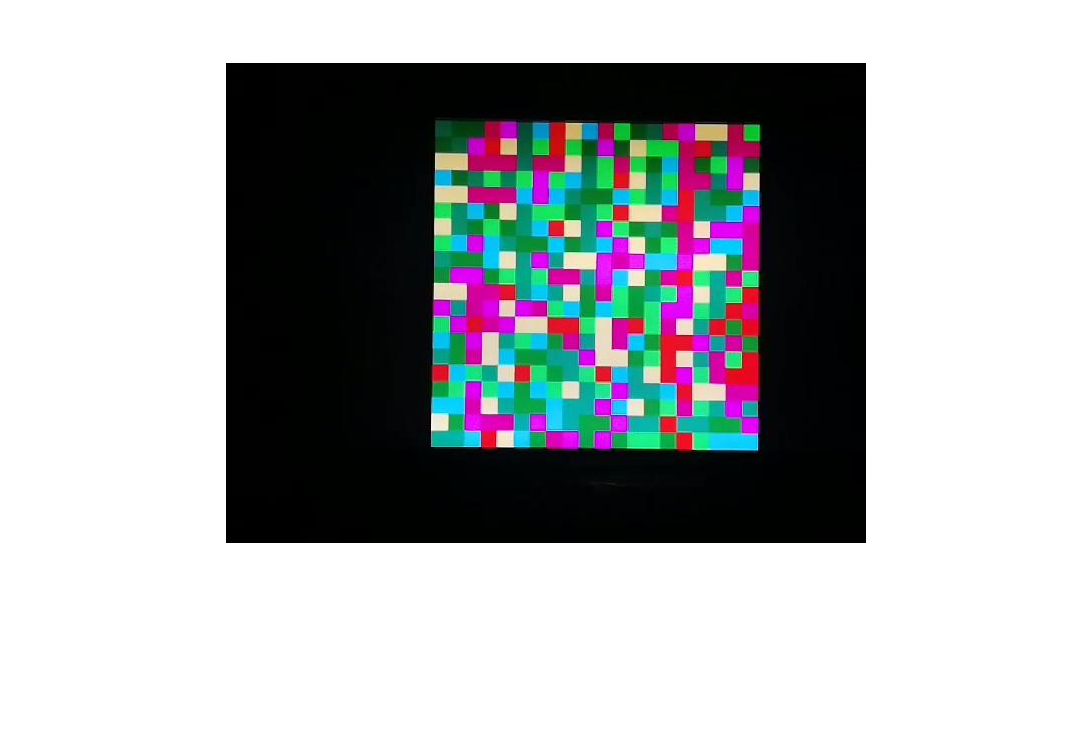

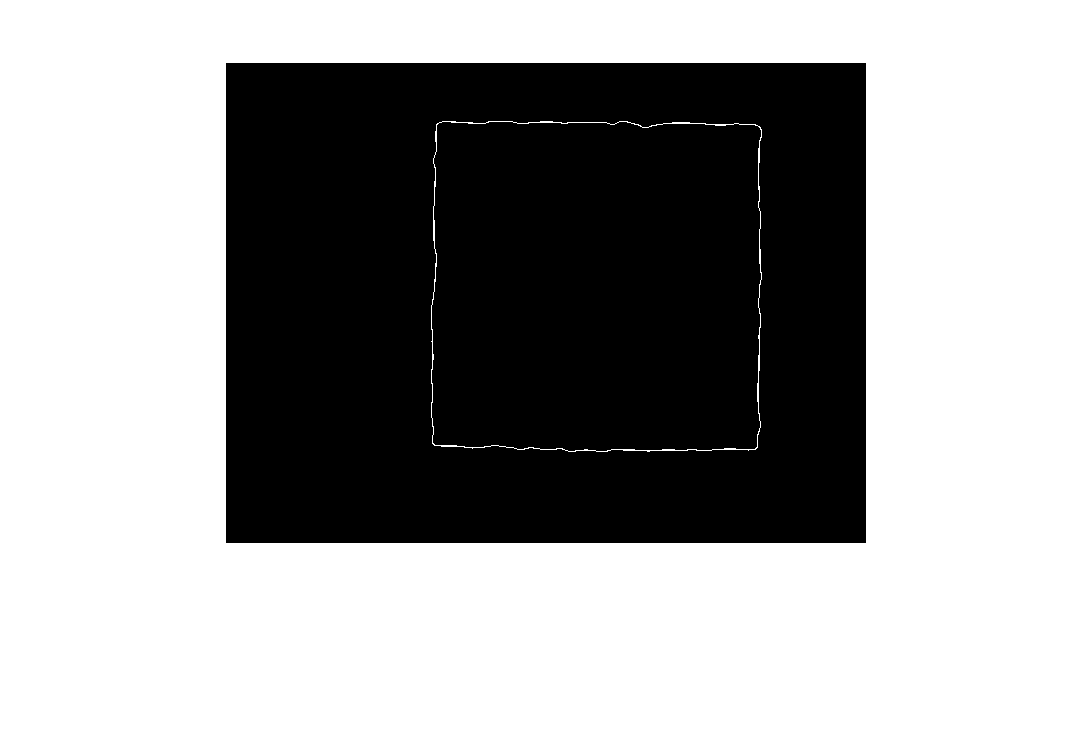

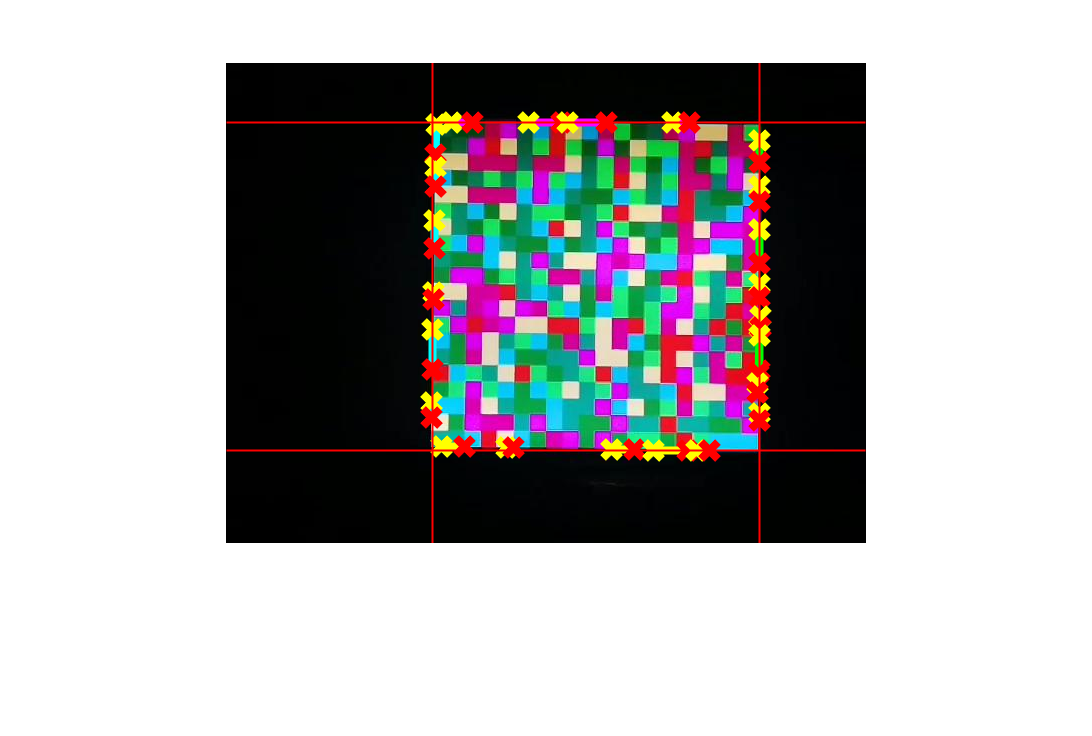

corners =   534.0000  388.0000
  534.0000   60.0000
  207.0000  388.0000
  207.0000   60.0000


img = imread('../Training data/7.jpg');
figure;
imshow(img);
corners=weighting(net,img,1)

C=semanticseg(img,net);
BW3=(C=='Frame');
BW3 = imfill(BW3,'holes');
BW3 = ExtractNLargestBlobs(BW3, 1);
[BW3,J]=find(BW3>max(BW3(:))/2);
IJ=[BW3,J];
[~,idx]=min(IJ*[1 1; -1 -1; 1 -1; -1 1].');
corners2=IJ(idx,:)

corners2 =     63   211
   386   531
    64   533
   380   207



corners = [mean([corners2(2,2) corners(1,1)]) mean([corners2(2,1) corners(1,2)]);...
           mean([corners2(3,2) corners(2,1)]) mean([corners2(3,1) corners(2,2)]);...
           mean([corners2(4,2) corners(3,1)]) mean([corners2(4,1) corners(3,2)]);...
           mean([corners2(1,2) corners(4,1)]) mean([corners2(1,1) corners(4,2)])]

corners =   532.5000  387.0000
  533.5000   62.0000
  207.0000  384.0000
  209.0000   61.5000


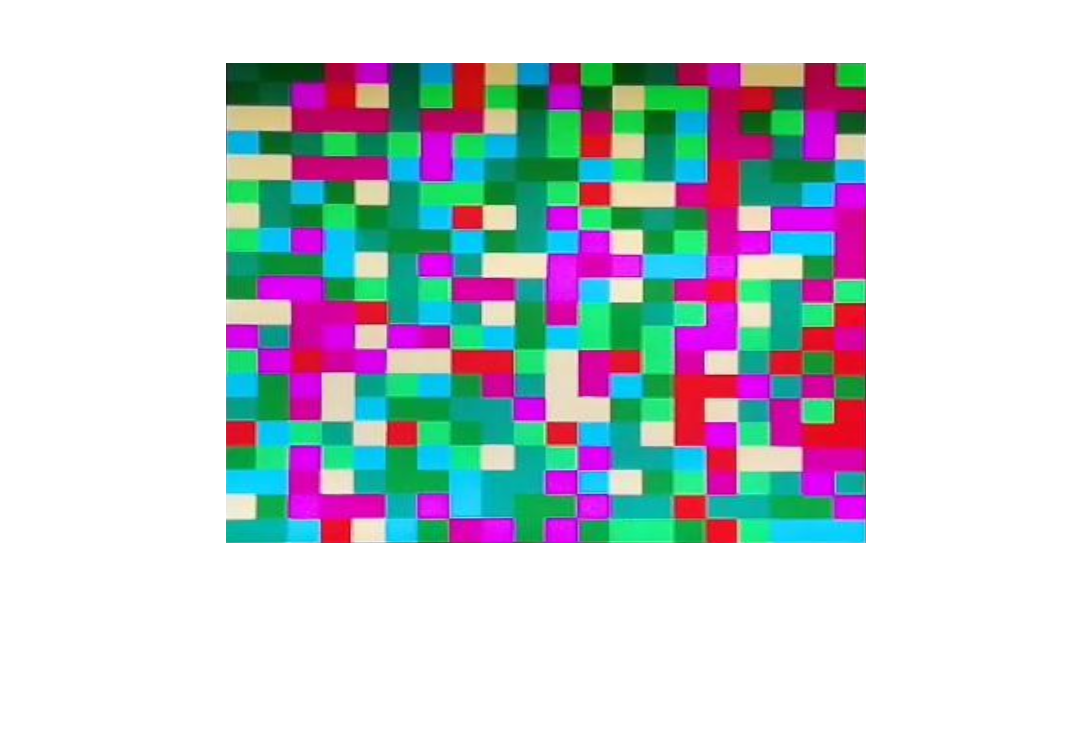


% Apply Perspective Warping followed by cropping of the frame 
movingPoints = [corners(4,1) corners(4,2); corners(2,1),corners(2,2); corners(1,1),corners(1,2); corners(3,1),corners(3,2)];%coordinate of distorted corners 
% movingPoints = [corners2(1,2) corners2(1,1); corners2(3,2),corners2(3,1); corners2(2,2),corners2(2,1); corners2(4,2),corners2(4,1)];%coordinate of distorted corners 
fixedPoints=[0 0;size(img,1) 0;size(img,1) size(img,2);0 size(img,2)]; %coordinate of image's corners

tform = fitgeotrans(movingPoints,fixedPoints,'projective');
R=imref2d(size(img),[1 size(img,1)],[1 size(img,2)]);
frame=imwarp(img,tform,'OutputView',R);

figure;
imshow(frame);


% Apply grid for visual analysis (Remove for final code)
numSymbols = 20;
figure
imshow(frame);
axis on;
[rows, columns, numberOfColorChannels] = size(frame)

rows = 480

columns = 640

numberOfColorChannels = 3

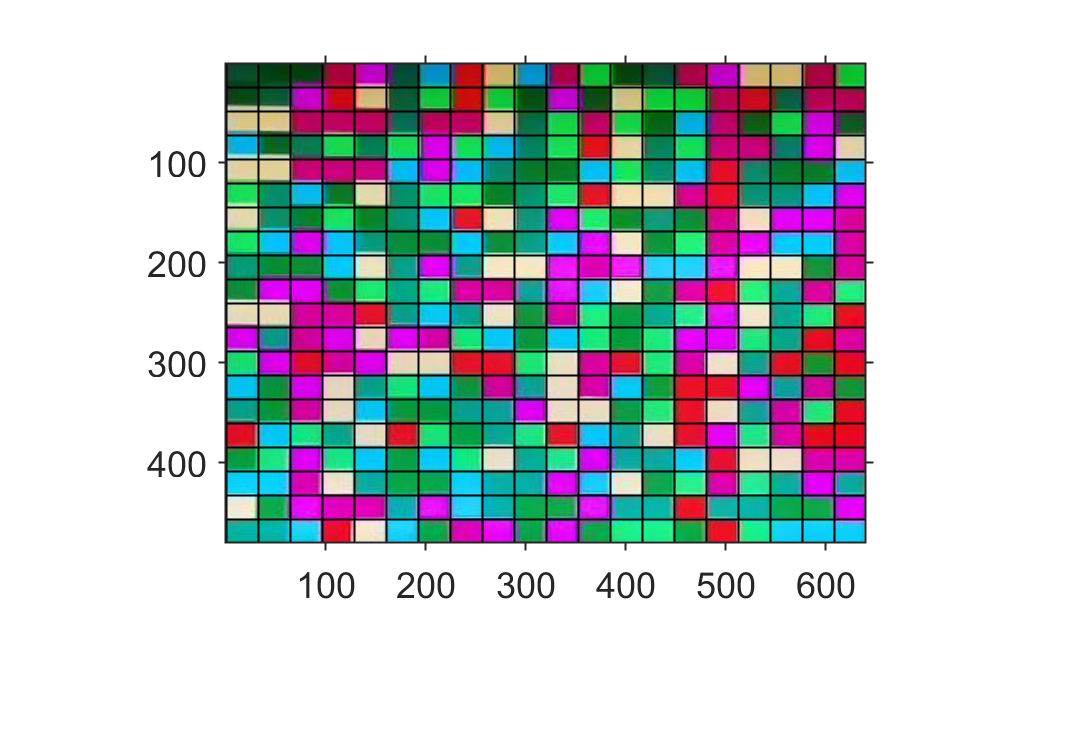

hold on;
for row = 1 : rows/numSymbols : rows
  line([1, columns], [row, row], 'Color', 'k');
end
for col = 1 : columns/numSymbols : columns
  line([col, col], [1, rows], 'Color', 'k');
end

function vertices=weighting(semanticNet,img,numOrig)

C=semanticseg(img,semanticNet);
featureMap=(C=='Frame');
% featureMap=(featureMap*255);

dim = size(img);
% K = (1/25)*ones(5); % smooth factor
% featureMap = conv2(featureMap,K,'same');
bwFeatureMap=edge(featureMap,'canny');
hold off
figure;
imshow(bwFeatureMap)

[H,T,R] = hough(bwFeatureMap);
P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
lines = houghlines(bwFeatureMap,T,R,P,'FillGap',5,'MinLength',7);
gradient=0;
aveX=0;
aveY=0;

for k = 1:length(lines)
    point1=lines(k).point1;
    point2=lines(k).point2;
    aveX=aveX+point1(1)+point2(1);
    aveY=aveY+point1(2)+point2(2);
    xy = [lines(k).point1; lines(k).point2];
    lines(k).dist=pdist(xy,"euclidean");
    gradient=((point1(2)-point2(2))/(0.0000000001+point1(1)-point2(1)));
    lines(k).gradient=gradient;
end

aveX=aveX/(2*length(lines));
aveY=aveY/(2*length(lines));
figure
imshow(img)
hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    point1=lines(k).point1;
    point2=lines(k).point2;
    gradient=lines(k).gradient;
    if abs(gradient)>1 && point1(1)>aveX
        lines(k).color='green';
    elseif abs(gradient)>1 && point1(1)<aveX
        lines(k).color='cyan';
    elseif abs(gradient)<1 && point1(2)<aveY
        lines(k).color='magenta';
    elseif abs(gradient)<1 && point1(2)>aveY
        lines(k).color='yellow';
    else
        'Not found'
    end
    %plot lines
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color',lines(k).color);
    % Plot beginnings and ends of lines
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
    hold on;
end

tab=struct2table(lines);
yArr=double(zeros(4,dim(2)));
sides=["green" "yellow" "cyan" "magenta"];
x=1:dim(2);
hold on
for i=1:4
    color=sides(i);
    rows=ismember(tab.color,color);
    tabTemp=tab(rows,:);
    if numOrig>height(tabTemp)
        num=height(tabTemp);
    else num=numOrig;
    end

    tabTemp=sortrows(tabTemp,'dist','descend');
    tabTemp=tabTemp(1:num,:);
    gradient=0;
    sumWeight=0;
    pointX=0;
    pointY=0;
    for j=1:height(tabTemp)
        weight=tabTemp(j,:).dist/tabTemp(1,:).dist;
        sumWeight=sumWeight+weight;
        gradient=gradient+weight*tabTemp(j,:).gradient;
        pointX=pointX+weight*(tabTemp(j,:).point1(1)+tabTemp(j,:).point2(1));
        pointY=pointY+weight*(tabTemp(j,:).point1(2)+tabTemp(j,:).point2(2));
    end
    gradient=gradient/sumWeight;
    
    
    pointX=pointX/(2*sumWeight);
    pointY=pointY/(2*sumWeight);
    
    b=pointY-gradient*pointX;
    y=polyval([gradient b],x);
    yArr(i,:)=y;
    plot(x,y,'r')
    hold on
end
hold on

curve=[x;yArr(1,:);x;yArr(2,:);x;yArr(3,:);x;yArr(4,:)];
vertices=double(zeros(4,2));
iteration=1;
for i=1:3
    for j=i:3

        P=InterX(curve(2*i-1:2*i,:),curve(1+2*j:2+2*j,:));
        if length(P)>0 && P(1)<dim(2) && P(2)<dim(1)
            vertices(iteration,:)=P;
            iteration=iteration+1;
        end
    end
end
% vertices=sortrows(vertices,[1 2])

% remove corners off the map 
idx = find( (vertices(2,:)<0) | (vertices(1,:)<0) );
vertices(idx,:) = [];
idx  = find((vertices(:,1)>dim(2)) | (vertices(:,2)>dim(1)));
vertices(idx,:) = [];
end


